%% Setup a cone mosaic
imageSize = [128, 128, 3];
display = displayCreate('CRT12BitDisplay');
prior   = load('sparsePrior.mat');

fovDegs = 0.20;
pupilSize = 3.0;
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', fovDegs, 'display', display, 'pupilSize', pupilSize, ...
    'integrationTime', 1.0);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 30.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.326980, Tolerange: 0.001000
Number of Delaunay triangulations: 8
[PASS:  1/ 3]. Adjusting cones between 30.00 44.96 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment:

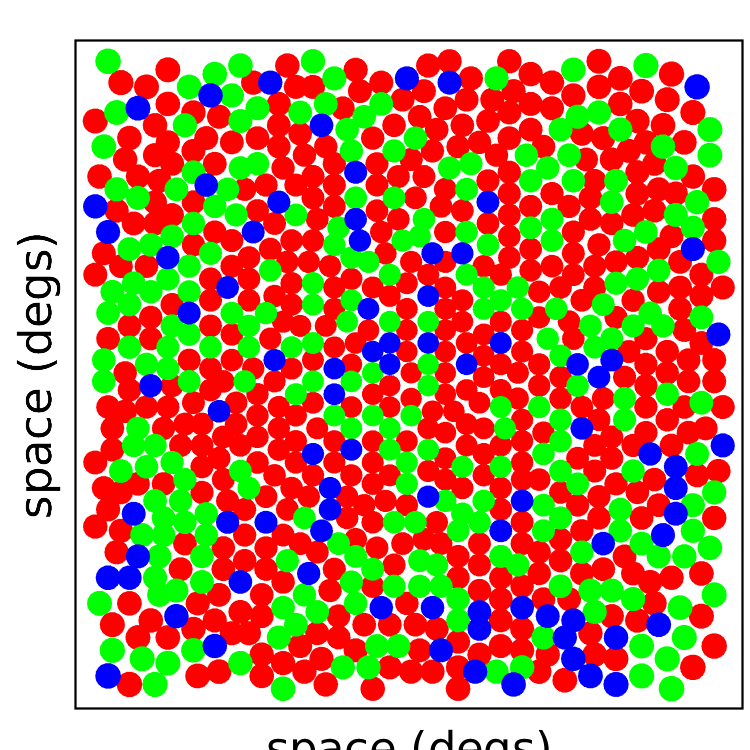


retina.resetSCone();
retina.reassignSCone(0.1);
retina.visualizeMosaic();

%% Regular optics
retina.PSF = oiCreate('human', pupilSize);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).


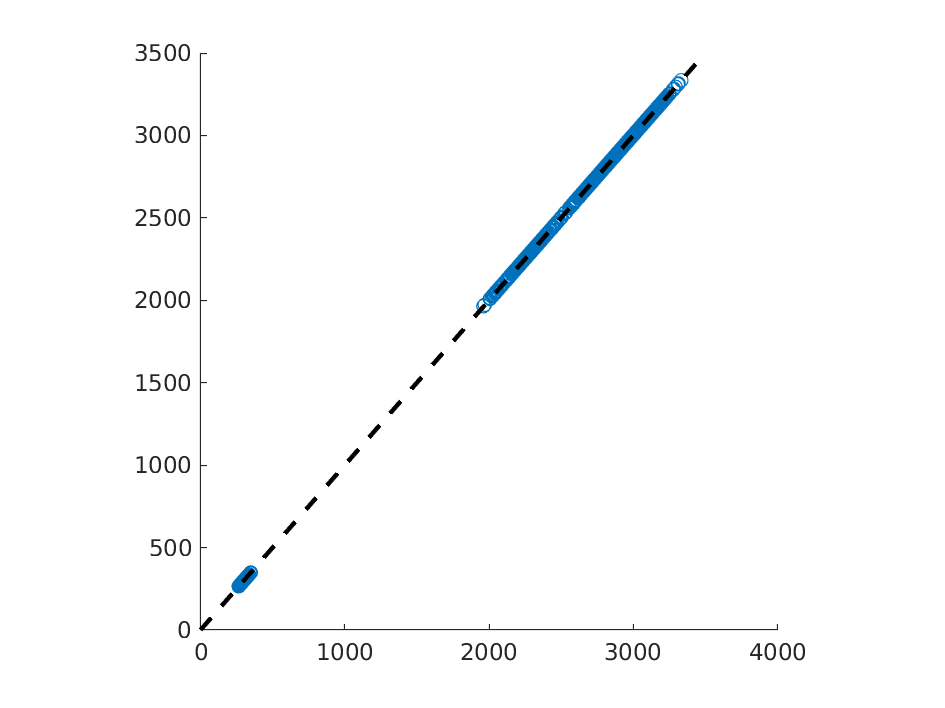

render = retina.forwardRender(imageSize, true, true, false);

render = double(render);

%% Compute cone excitation with gratings
spatialFreq = 96;

rmsContrast = 1.0;
chromaDir = [1.0, 1.0, 1.0]';
chromaDir = chromaDir / norm(chromaDir) * rmsContrast;

gratingScene = ...
    createGratingScene(chromaDir, spatialFreq, 'fovDegs', fovDegs, 'pixelsNum', 1024);

crst = 1.0;
[theSceneSequence, ~] = gratingScene.compute(crst);

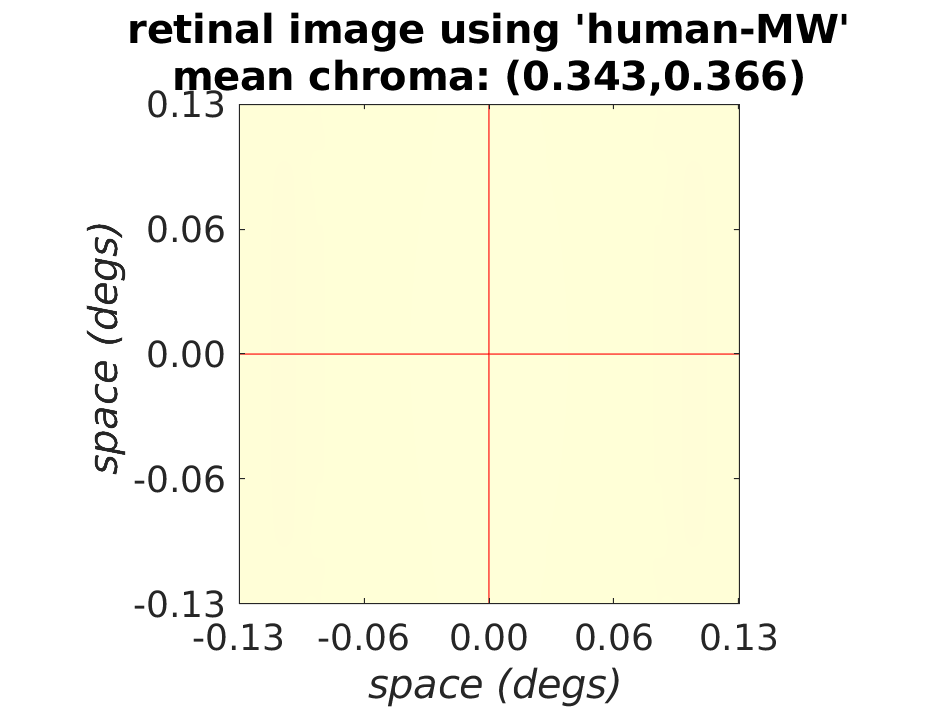

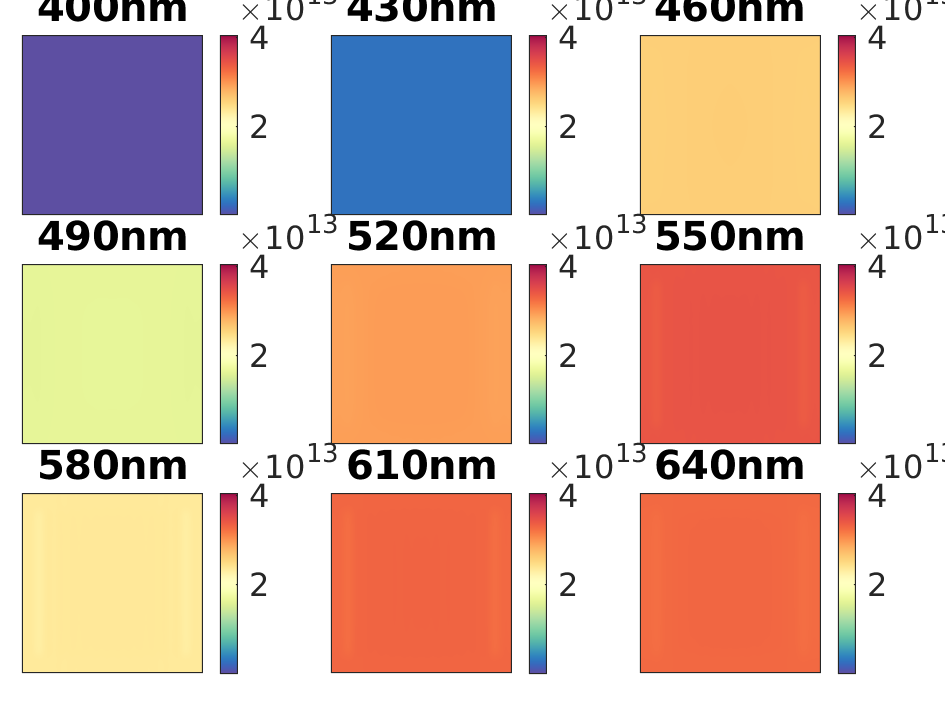

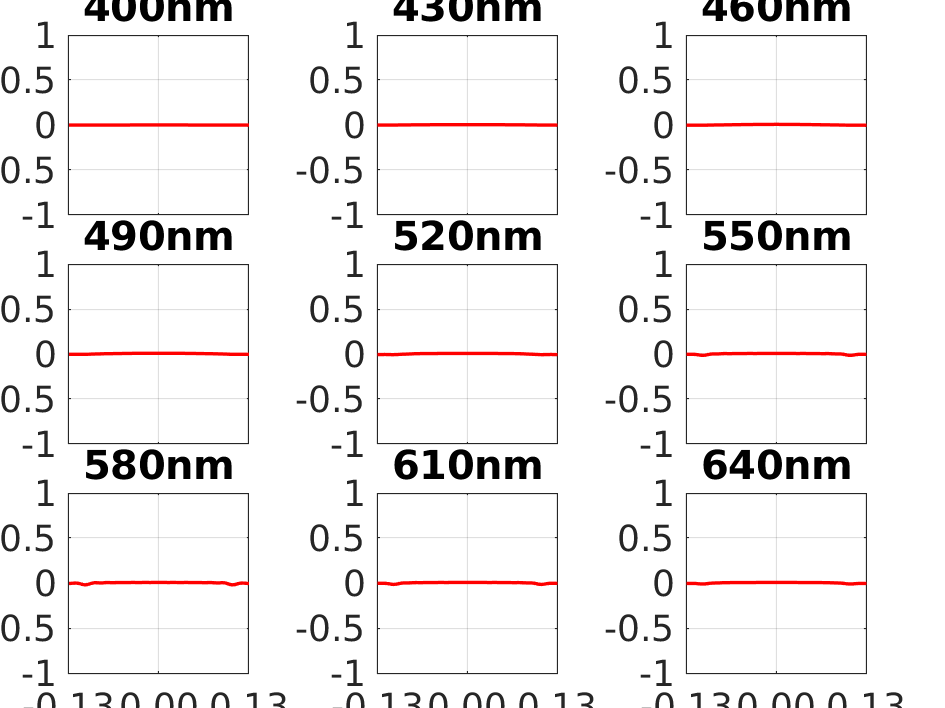

% Compute response from scene
[~, allCone] = retina.computeWithScene(theSceneSequence{:});
visualizeOpticalImage(retina.LastOI, 'displayRadianceMaps', true, ...
                'displayRetinalContrastProfiles', true);

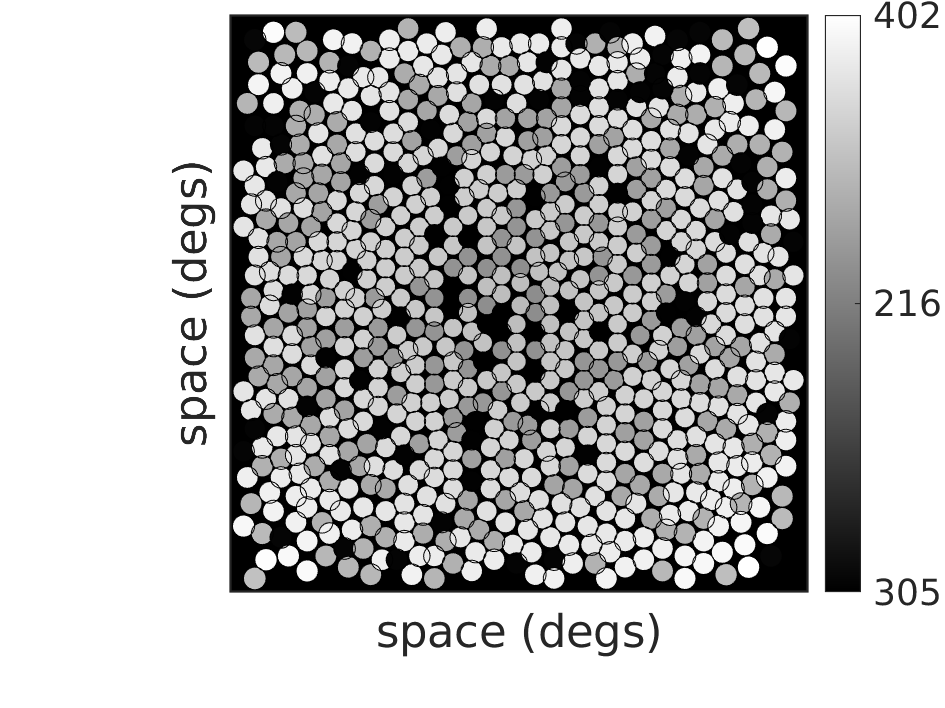

% Visualize pattern of cone excitation
retina.visualizeExcitation();

% Run image reconstruction
% construct image estimator
regPara = 1e-3; stride = 4;
estimator = PoissonSparseEstimator(gpuArray(single(render)), ...
    inv(prior.regBasis), prior.mu', regPara, stride, imageSize);

% estimate images
reconImage = ...
    estimator.runEstimate(allCone, 'maxIter', 200, ...
    'display', 'iter', 'gpu', true);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.720145e+07    0.000e+00    6.371e+01
    1       2   -1.723651e+07    0.000e+00    1.260e+02    4.647e+01
    2       3   -1.727233e+07    0.000e+00    5.718e+01    1.974e+01
    3       4   -1.727306e+07    0.000e+00    6.260e+01    2.255e+00
    4       5   -1.727326e+07    0.000e+00    1.859e+01    1.654e+00
    5       6   -1.727357e+07    0.000e+00    1.800e+01    3.105e+00
    6       7   -1.727422e+07    0.000e+00    9.732e+00    7.084e+00
    7       8   -1.727527e+07    0.000e+00    1.185e+01    1.253e+01
    8       9   -1.727623e+07    0.000e+00    9.776e+00    1.505e+01
    9      10   -1.727705e+07    0.000e+00    1.039e+01    7.437e+00
   10      11   -1.727756e+07    0.000e+00    6.219e+00    4.921e+00
   11      12   -1.727784e+07    0.000e+00    3.705e+00    3.996e+00
   12      13   -1.727804e+07    0.000e+00    3

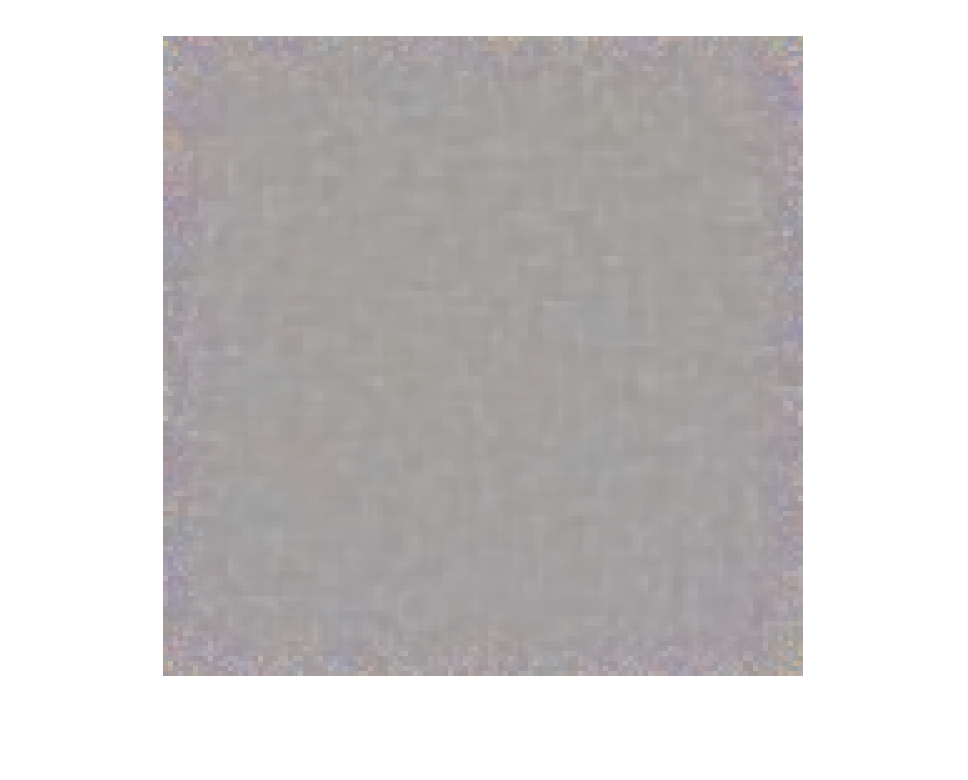

% show image
figure();
imshow(gammaCorrection(reconImage, display), ...
    'InitialMagnification', 500);

%% Turn off optics
% Use a large pupil size to reduce the effect of diffraction
diffPupil = 10.0;
retina.PSF = ConeResponse.psfDiffLmt(diffPupil);

renderDiflmt = retina.forwardRender(imageSize, true, true, false);
renderDiflmt = double(renderDiflmt);

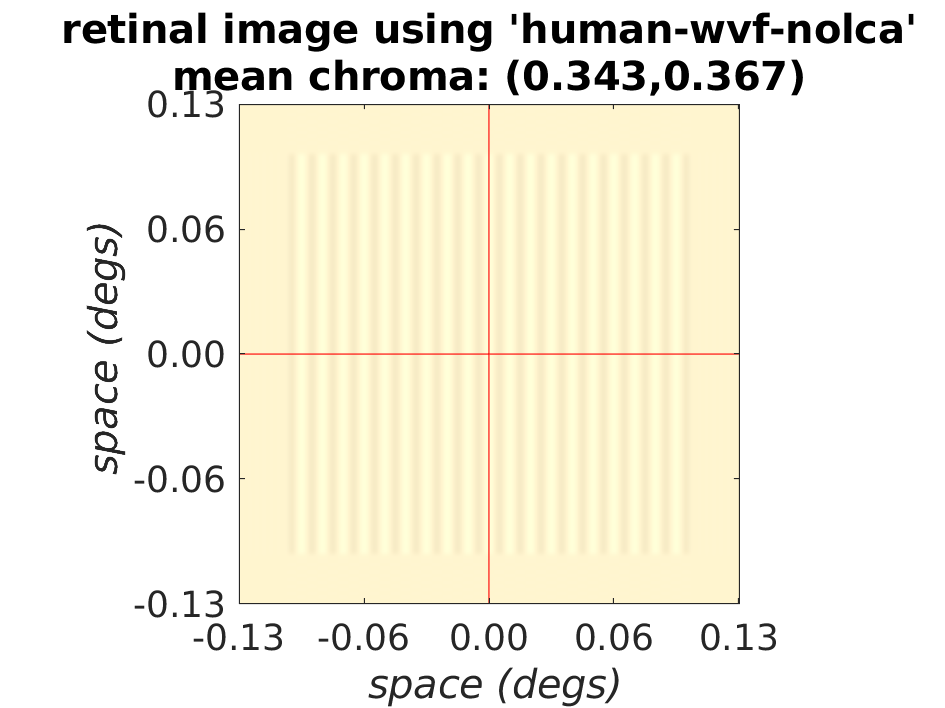

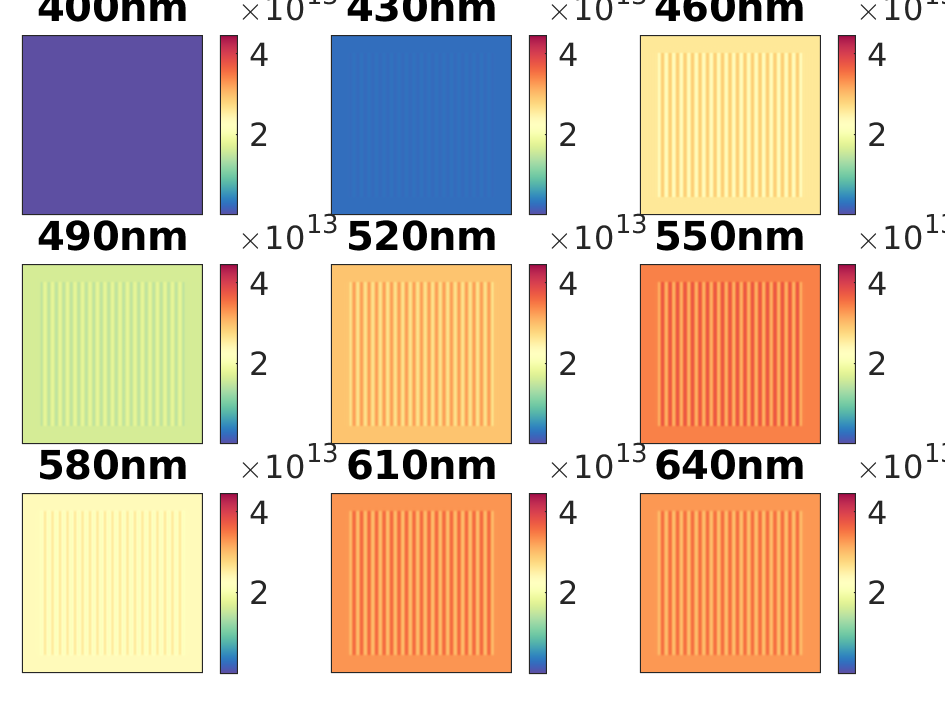

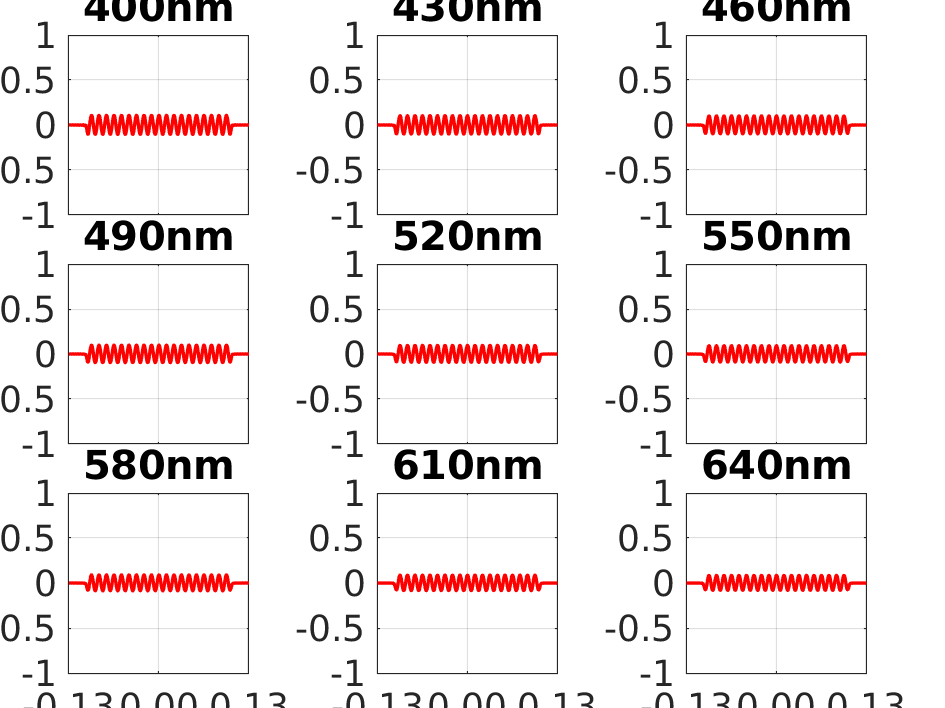

%% Compute cone excitation with gratings
spatialFreq = 96;

rmsContrast = 1.0;
chromaDir = [1.0, 1.0, 1.0]';
chromaDir = chromaDir / norm(chromaDir) * rmsContrast;

gratingScene = ...
    createGratingScene(chromaDir, spatialFreq, 'fovDegs', fovDegs, 'pixelsNum', 1024);

crst = 0.25;
[theSceneSequence, temporalSupport] = gratingScene.compute(crst);

% Compute response from scene
[~, allCone] = retina.computeWithScene(theSceneSequence{:});
visualizeOpticalImage(retina.LastOI, 'displayRadianceMaps', true, ...
                'displayRetinalContrastProfiles', true);

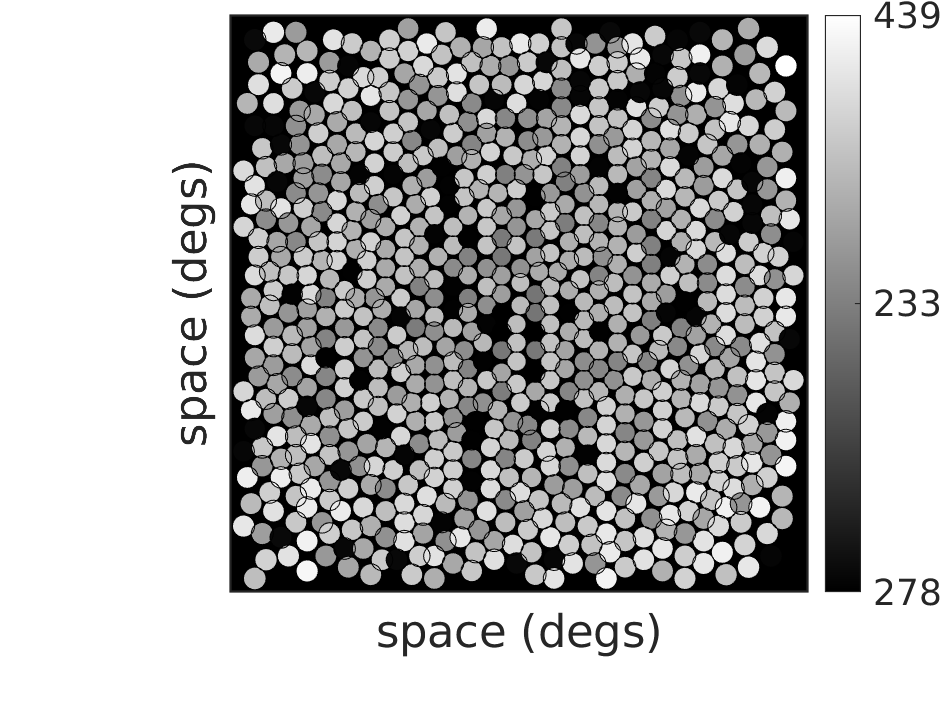

% Visualize pattern of cone excitation
retina.visualizeExcitation();

% Run image reconstruction
% estimate images
reconImage = ...
    estimator.runEstimate(allCone, 'maxIter', 200, ...
    'display', 'iter', 'gpu', true);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.729395e+07    0.000e+00    6.316e+01
    1       2   -1.732451e+07    0.000e+00    1.247e+02    4.709e+01
    2       3   -1.736379e+07    0.000e+00    5.566e+01    2.031e+01
    3       4   -1.736448e+07    0.000e+00    6.067e+01    2.137e+00
    4       5   -1.736472e+07    0.000e+00    3.158e+01    1.731e+00
    5       6   -1.736508e+07    0.000e+00    1.819e+01    3.282e+00
    6       7   -1.736579e+07    0.000e+00    1.104e+01    6.883e+00
    7       8   -1.736680e+07    0.000e+00    1.246e+01    9.290e+00
    8       9   -1.736790e+07    0.000e+00    1.246e+01    1.061e+01
    9      10   -1.736884e+07    0.000e+00    9.532e+00    1.042e+01
   10      11   -1.736965e+07    0.000e+00    5.727e+00    4.103e+00
   11      12   -1.736995e+07    0.000e+00    4.479e+00    3.244e+00
   12      13   -1.737020e+07    0.000e+00    4

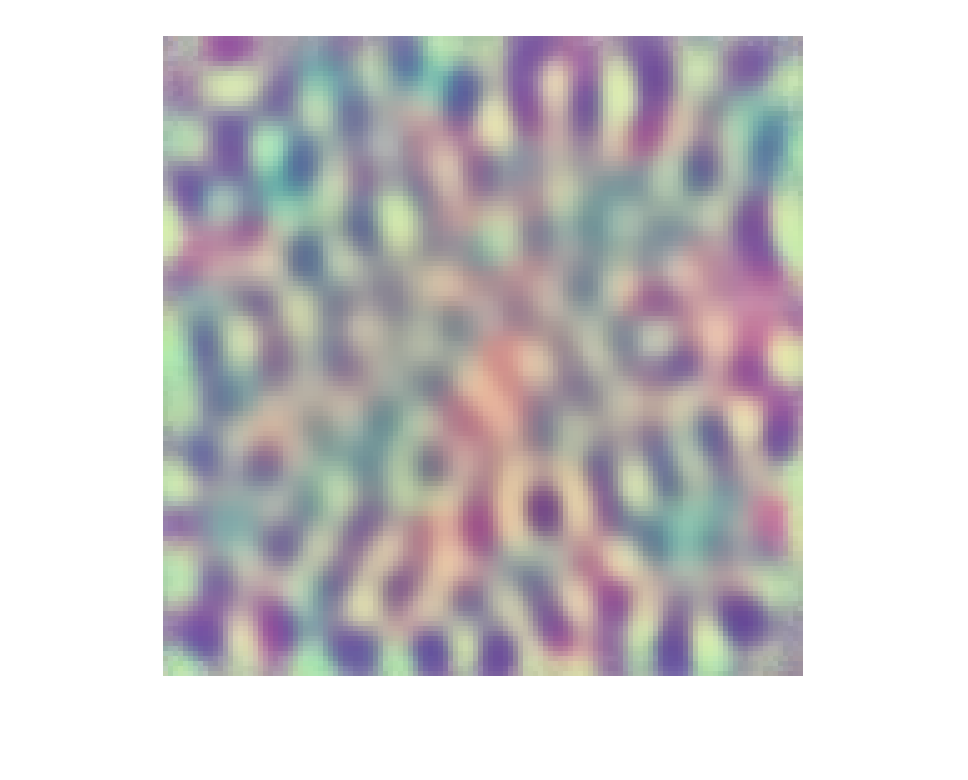


% show image
figure();
imshow(gammaCorrection(reconImage, display), ...
    'InitialMagnification', 500);

% Run the calculation with rectangular mosaic 
% Setup a cone mosaic
imageSize = [128, 128, 3];
display = displayCreate('CRT12BitDisplay');
prior   = load('sparsePrior.mat');

fovDegs = 1.0;
pupilSize = 3.0;

eccX = 10.0; eccY = 10.0;
retina = ConeResponsePeripheral(eccX, eccY, 'fovealDegree', fovDegs, ...
    'display', display, 'pupilSize', pupilSize);

Override, will not create mosaic and optics object 

Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 63
Scones after making an S-cone free central patch: 58 (added Lcones:4, added Mcones:1)
Scones after pass 1: 35 (added Lcones:16, added Mcones:9)
Scones after pass 2: 28 (added Lcones:6, added Mcones:4)
Scones after pass 3: 25 (added Lcones:2, added Mcones:1)
Scones after pass 4: 24 (added Lcones:0, added Mcones:1)
Scones after pass 5: 24 (added Lcones:0, added Mcones:0)


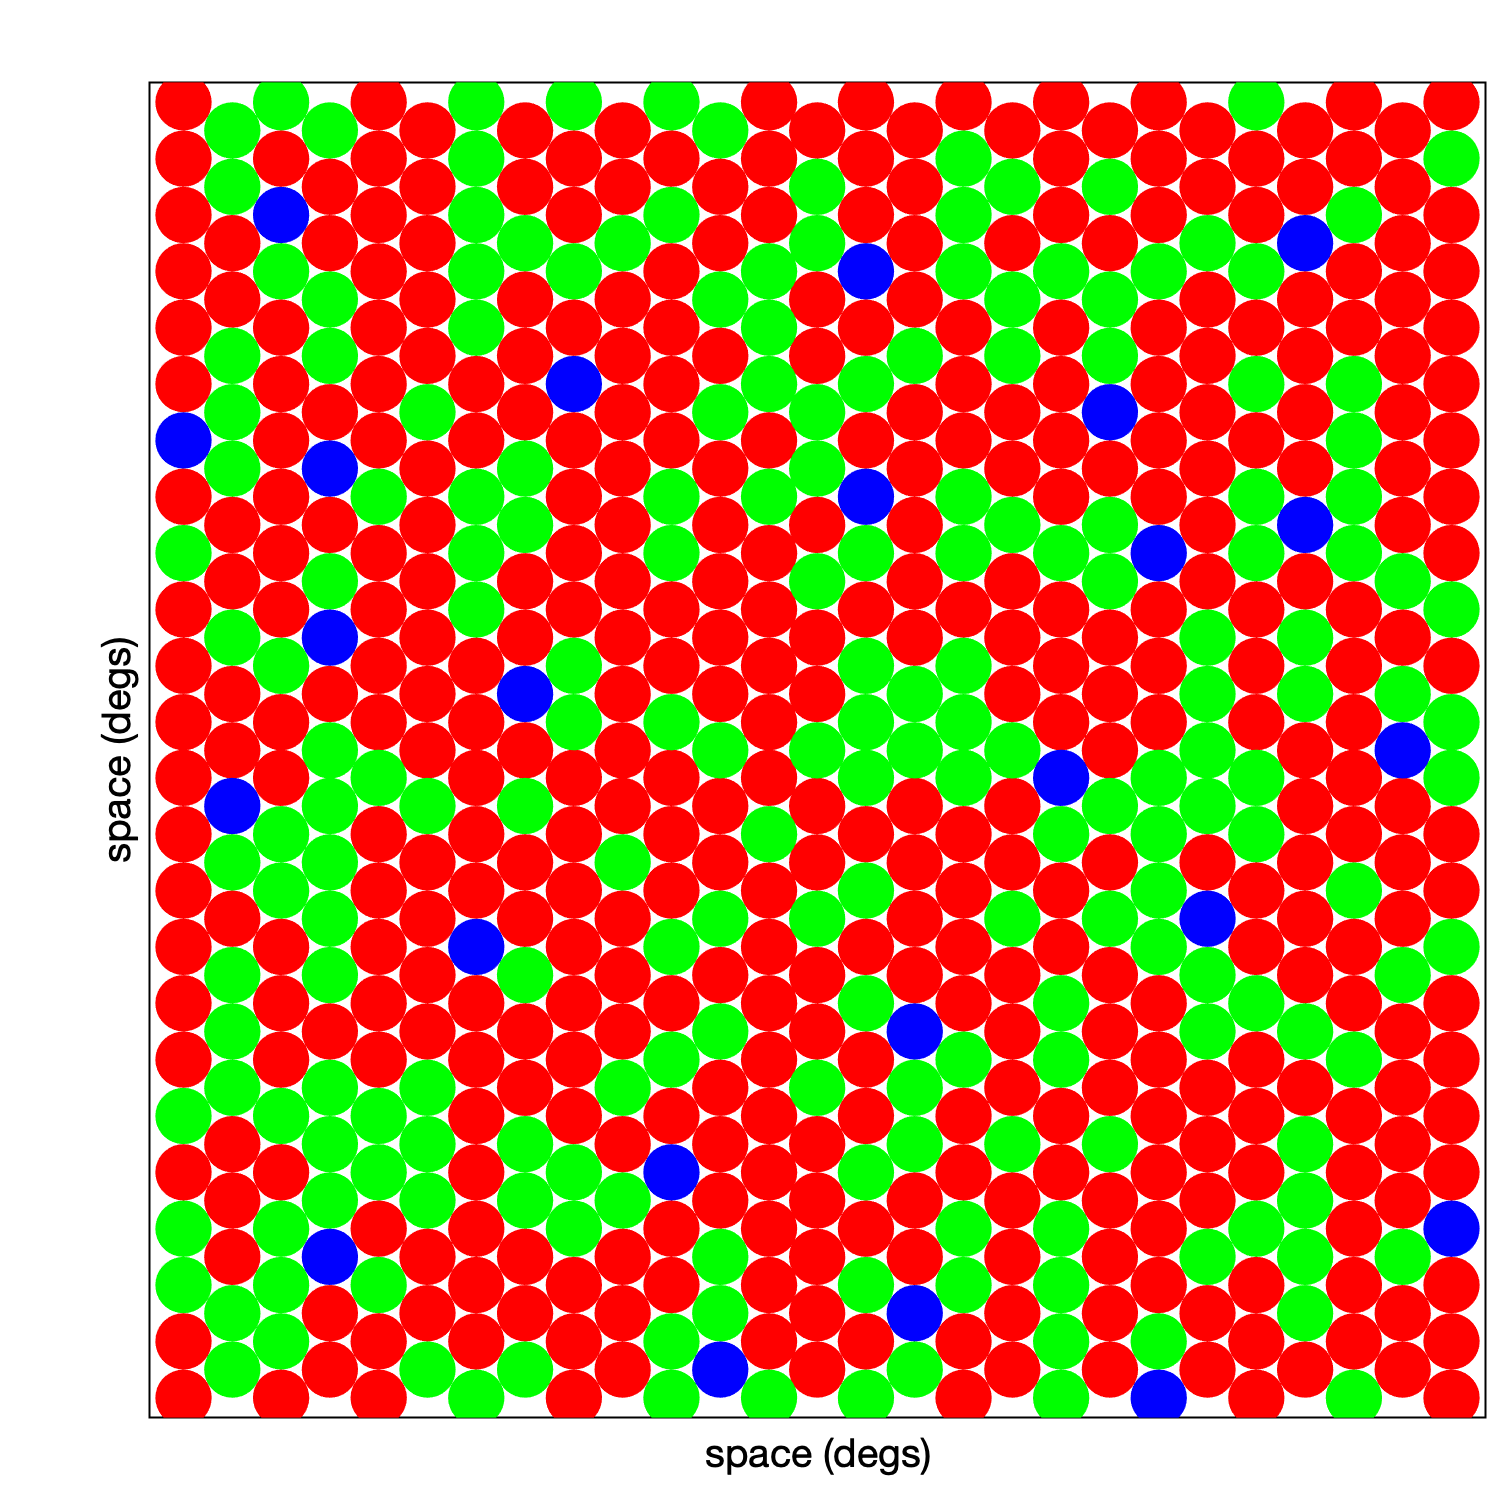


retina.visualizeMosaic();

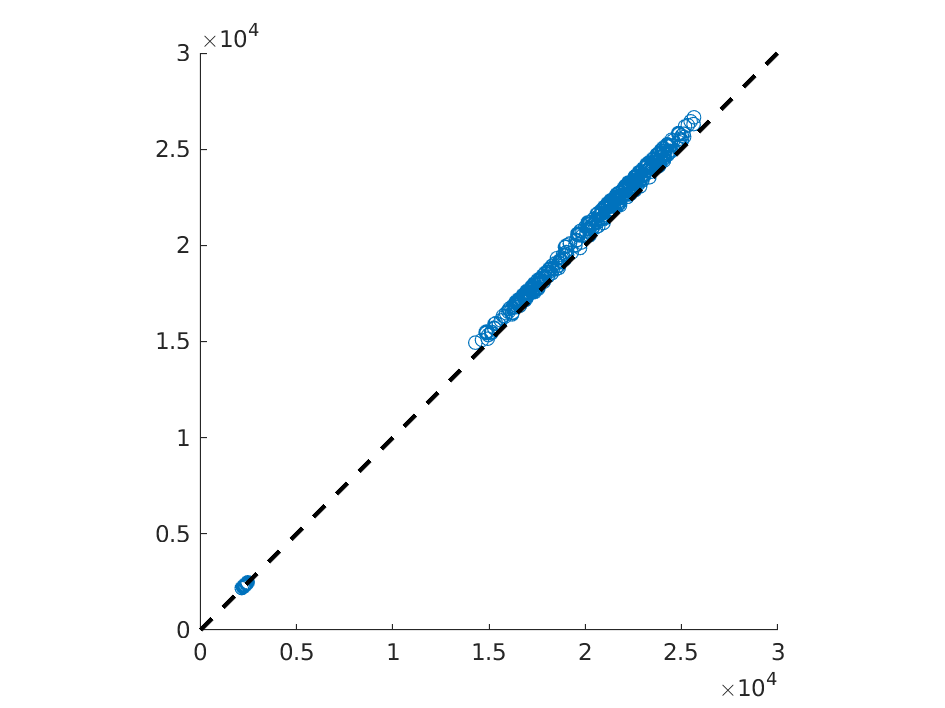

% Render matrix
render = retina.forwardRender(imageSize, true, true, false);

render = double(render);

%% Turn off optics
% Use a large pupil size to reduce the effect of diffraction
diffPupil = 10.0;
retina.PSF = ConeResponse.psfDiffLmt(diffPupil);

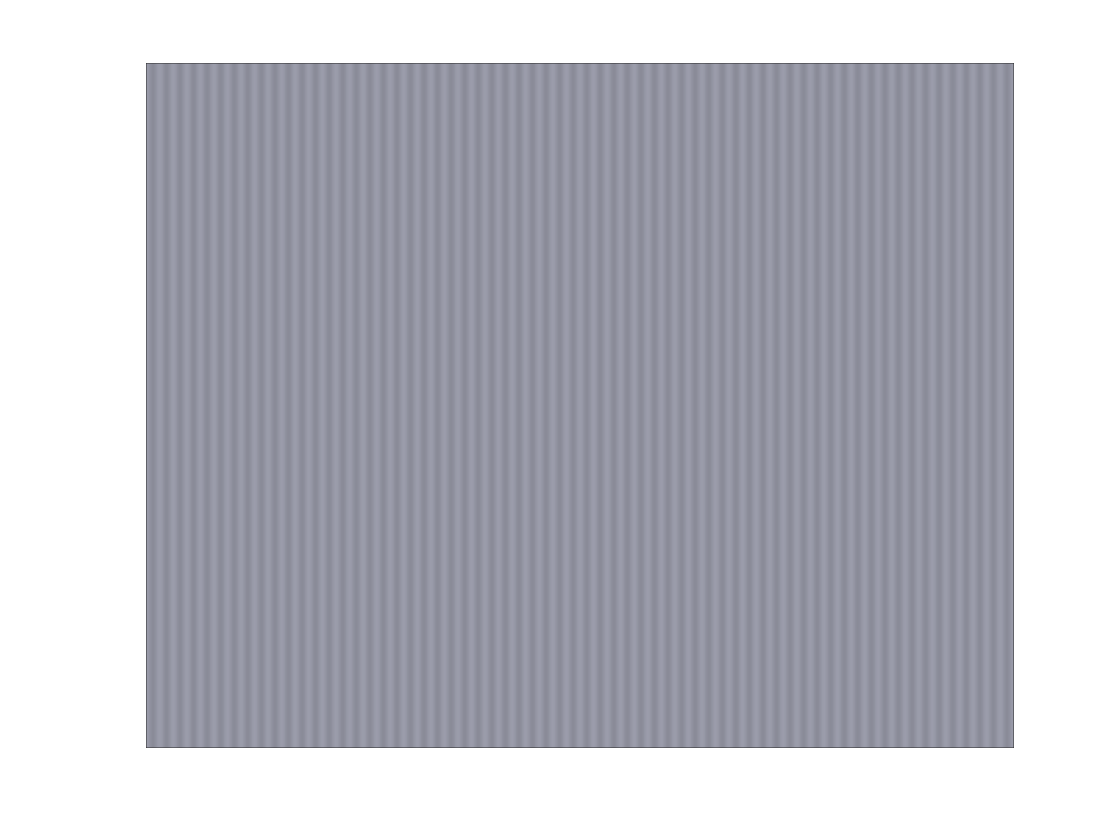

%% Compute cone excitation with gratings
spatialFreq = 64;

rmsContrast = 1.0;
chromaDir = [1.0, 1.0, 1.0]';
chromaDir = chromaDir / norm(chromaDir) * rmsContrast;

gratingScene = ...
    createGratingScene(chromaDir, spatialFreq, 'fovDegs', fovDegs, 'pixelsNum', 2048);

crst = 0.2;
[theSceneSequence, ~] = gratingScene.compute(crst);

figure();
gratingScene.visualizeStaticFrame(theSceneSequence);

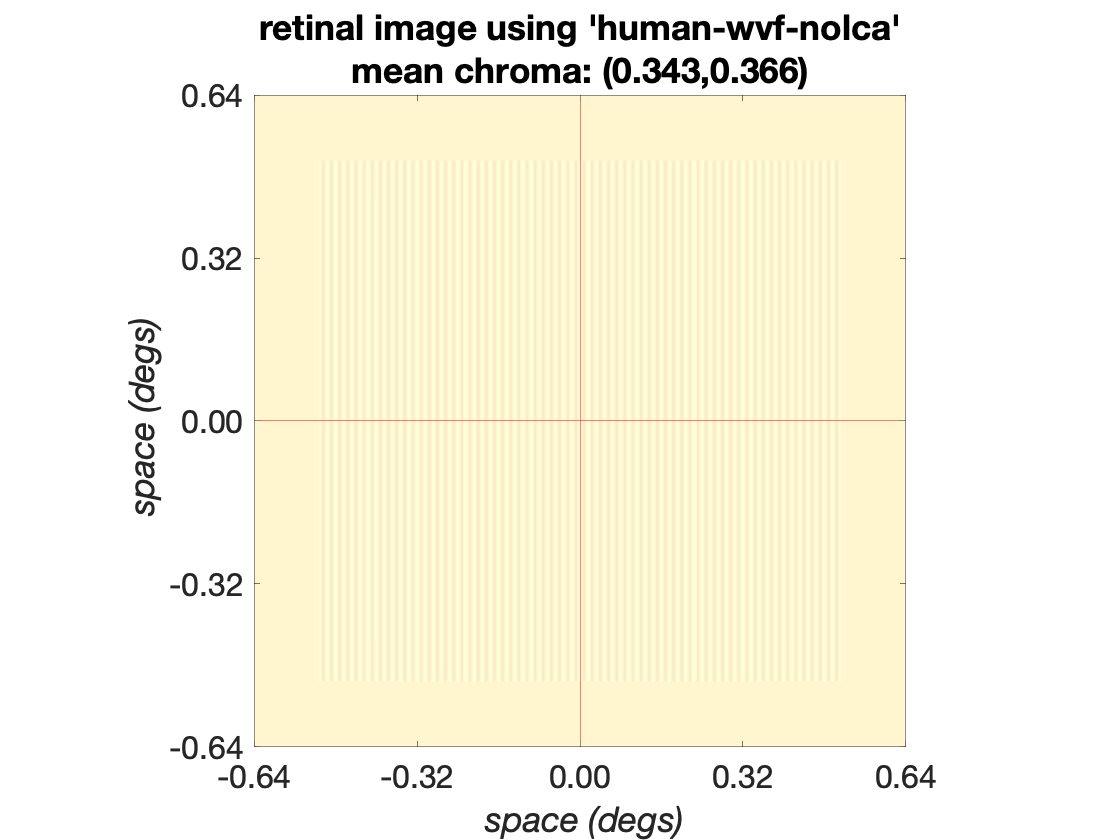

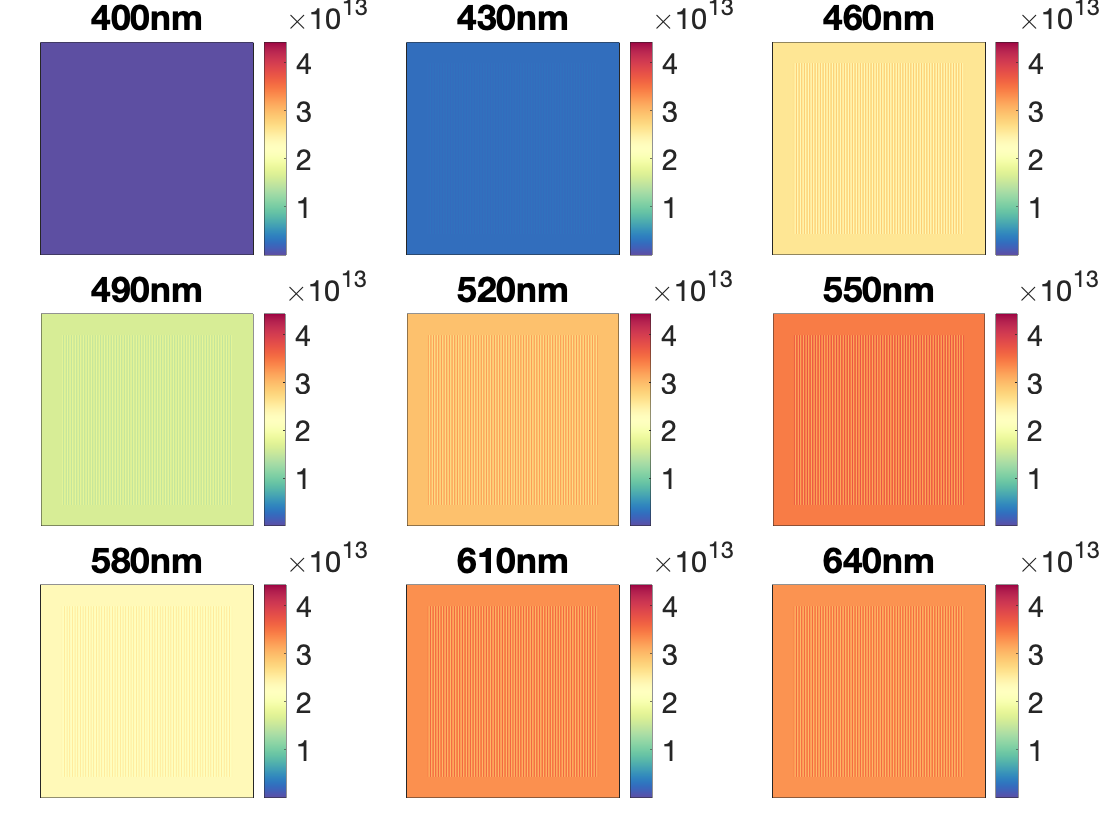

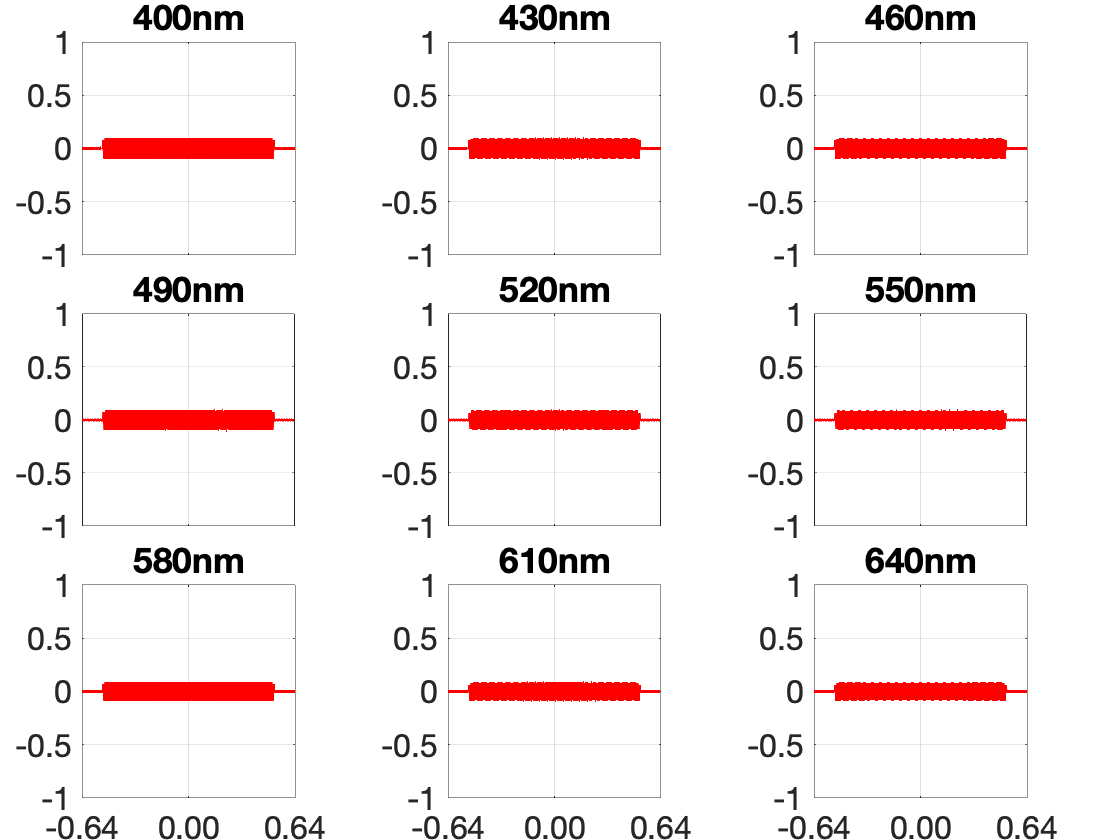

% Compute response from scene
[~, allCone] = retina.computeWithScene(theSceneSequence{:});
visualizeOpticalImage(retina.LastOI, 'displayRadianceMaps', true, ...
                'displayRetinalContrastProfiles', true);

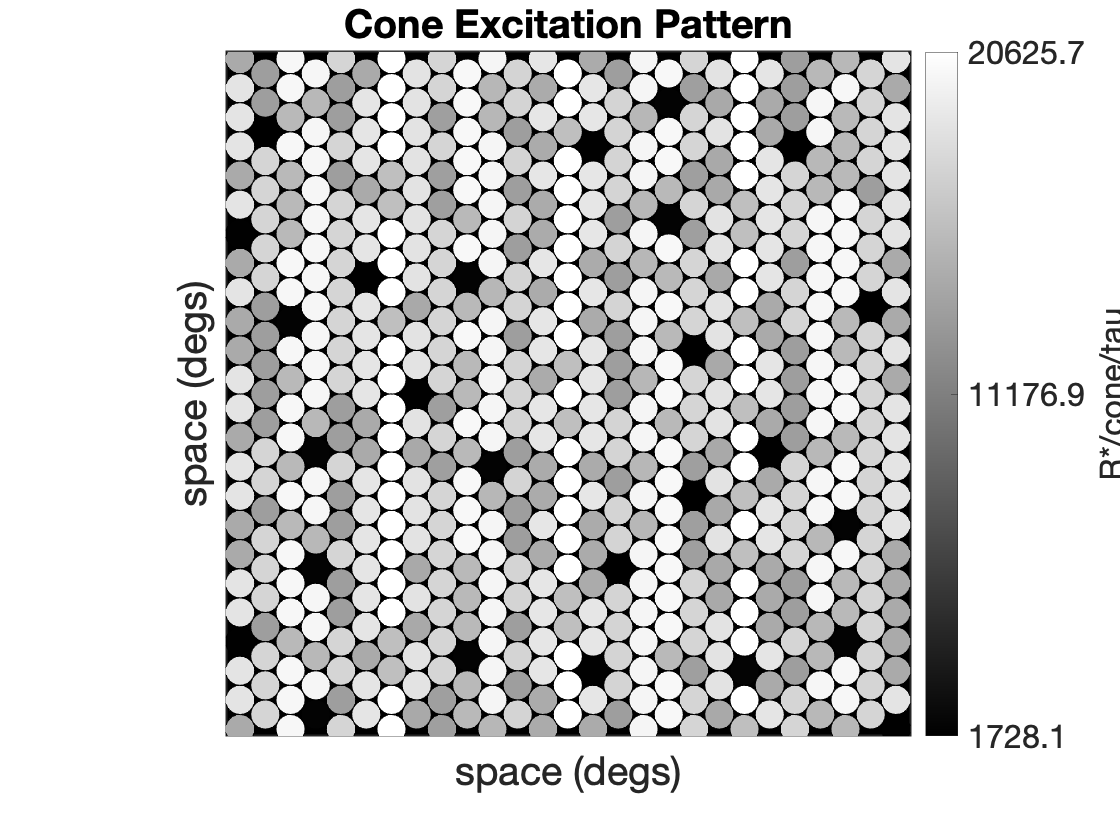

% Visualize pattern of cone excitation
retina.visualizeExcitation();

% Run image reconstruction
% construct image estimator
regPara = 1e-4; stride = 4;
estimator = PoissonSparseEstimator(render, inv(prior.regBasis), ...
    prior.mu', regPara, stride, imageSize);

% estimate images
reconImage = ...
    estimator.runEstimate(allCone, 'maxIter', 200, ...
    'display', 'iter', 'gpu', false);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.223532e+07    0.000e+00    1.605e+03
    1       2   -9.289304e+07    0.000e+00    1.048e+03    2.430e+01
    2       3   -9.290792e+07    0.000e+00    1.036e+03    6.411e-01
    3       4   -9.295764e+07    0.000e+00    9.966e+02    2.164e+00
    4       5   -9.301752e+07    0.000e+00    9.488e+02    2.666e+00
    5       6   -9.307807e+07    0.000e+00    8.999e+02    2.762e+00
    6       7   -9.313577e+07    0.000e+00    8.521e+02    2.700e+00
    7       8   -9.319726e+07    0.000e+00    7.998e+02    2.976e+00
    8       9   -9.325254e+07    0.000e+00    7.517e+02    2.783e+00
    9      10   -9.329755e+07    0.000e+00    7.508e+02    2.340e+00
   10      11   -9.334253e+07    0.000e+00    7.868e+02    2.436e+00
   11      12   -9.337016e+07    0.000e+00    8.091e+02    1.560e+00
   12      13   -9.343444e+07    0.000e+00    8

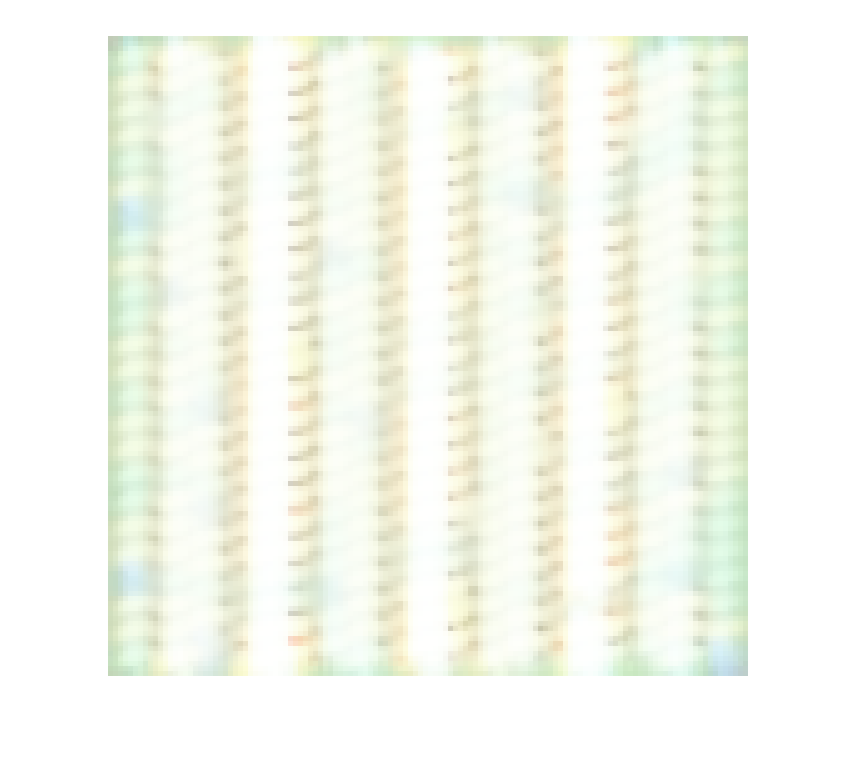


% show image
figure();
imshow(gammaCorrection(reconImage, display), ...
    'InitialMagnification', 500);